% Plant
A_hor = [-1/t_V,  0, 0, 0, 0;
          cm(1)/I_yz_lookup(1), 0, 0, 0, 0;
          0, 1, 0, 0, 0;
          0, 0, 0, 0, 1;
          0, 0, T_max/m(1), 0, 0];

b_hor = [1/t_V; 0; 0; 0; 0];
Ts_hor = 1/(100);

Rate controller

% Requirments
zeta = 1;
ts2 = 1;
wn = 4/(zeta*ts2);


p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_rate = [0, 1, 0, 0, 0];
d_rate = 0;
sysC = ss(A_hor,b_hor,c_rate,d_rate)

sysC =
 
  A = 
            x1       x2       x3       x4       x5
   x1      -10        0        0        0        0
   x2  0.03872        0        0        0        0
   x3        0        1        0        0        0
   x4        0        0        0        0        1
   x5        0        0    15.62        0        0
 
  B = 
       u1
   x1  10
   x2   0
   x3   0
   x4   0
   x5   0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



pls = pole(sysC)

pls =      0
   -10
     0
     0
     0


zers = zero(sysC)

zers =      0
     0
     0


sysD_rate = c2d(sysC,Ts_hor,'zoh');

% Controller

[C_rate,info] = pidtune(sysD_rate,'PI')

C_rate =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 77.7, Ki = 51.6, Ts = 0.01
 
Sample time: 0.01 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 2.9486
           PhaseMargin: 60.0000


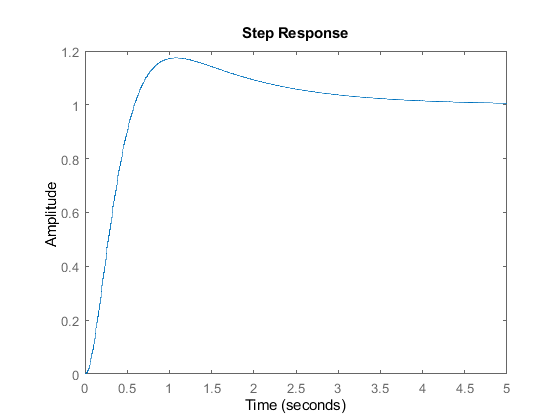

step(feedback(C_rate*sysD_rate,1))


% Equivalent plant
A_rate = [A_hor-b_hor*C_rate.Kp*c_rate, b_hor*C_rate.Ki;
         -c_rate              , 0];
b_rate = [b_hor*C_rate.Kp;1];

Angle controller

% Requirments
zeta = 1;
ts2 = 1;
wn = 4/(zeta*ts2);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_ang = [0, 0, 1, 0, 0, 0];
d_ang = 0;
sysC = ss(A_rate,b_rate,c_ang,d_ang)

sysC =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1      -10     -777        0        0        0    515.7
   x2  0.03872        0        0        0        0        0
   x3        0        1        0        0        0        0
   x4        0        0        0        0        1        0
   x5        0        0    15.62        0        0        0
   x6        0       -1        0        0        0        0
 
  B = 
        u1
   x1  777
   x2    0
   x3    0
   x4    0
   x5    0
   x6    1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



pls = pole(sysC)

pls =    0.0000 + 0.0000i
  -4.5408 + 1.0620i
  -4.5408 - 1.0620i
  -0.9183 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


zers = zero(sysC)

zers =    -0.6638
         0
         0


sysD_ang = c2d(sysC,Ts_hor,'zoh');

% Controller
[C_ang,info] = pidtune(sysD_ang,'P')

C_ang =
 
  Kp = 1.35
 
P-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5887
           PhaseMargin: 60.0041


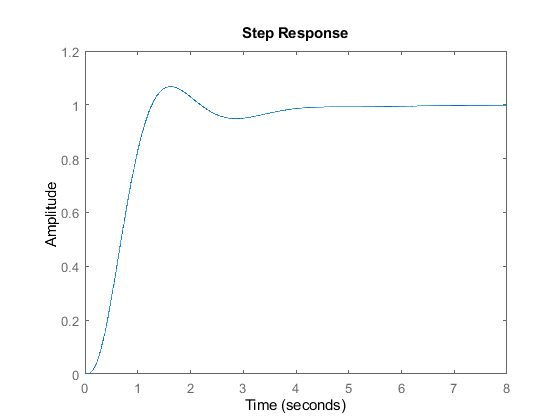

step(feedback(C_ang*sysD_ang,1))

S = stepinfo(step(feedback(C_ang*sysD_ang,1)))

S = struct with fields:
        RiseTime: 77.5893
    SettlingTime: 373.2070
     SettlingMin: 0.9029
     SettlingMax: 1.0676
       Overshoot: 6.9518
      Undershoot: 0
            Peak: 1.0676
        PeakTime: 163



% Equivalent plant
A_ang = A_rate - b_rate*C_rate.Kp*c_ang;
b_ang = b_rate*(C_rate.Kp/T_max);

 Velocity controller

% Requirments
zeta = 1;
ts2 = 3;
wn = 4/(zeta*ts2);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)];

p_z_want = exp(p_s_want*Ts_hor);

% Plant
c_vel = [0, 0, 0, 0, 1, 0];
d_vel = 0;

sysC = ss(A_ang,b_ang,c_vel,d_vel)

sysC =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1         -10        -777  -6.037e+04           0           0       515.7
   x2     0.03872           0           0           0           0           0
   x3           0           1           0           0           0           0
   x4           0           0           0           0           1           0
   x5           0           0       15.62           0           0           0
   x6           0          -1       -77.7           0           0           0
 
  B = 
           u1
   x1   60.37
   x2       0
   x3       0
   x4       0
   x5       0
   x6  0.0777
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



pls = pole(sysC)

pls =    0.0000 + 0.0000i
 -16.4951 + 0.0000i
   3.5788 +11.3648i
   3.5788 -11.3648i
  -0.6626 + 0.0000i
   0.0000 + 0.0000i


zers = zero(sysC)

zers =    -0.6638
         0


sysD_vel = c2d(sysC,Ts_hor,'zoh');

% Controller
[C_vel,info] = pidtune(sysD_vel,'P')

C_vel =
 
  Kp = 2.3e+03
 
P-only controller.



info = struct with fields:
                Stable: 0
    CrossoverFrequency: 17.3459
           PhaseMargin: NaN


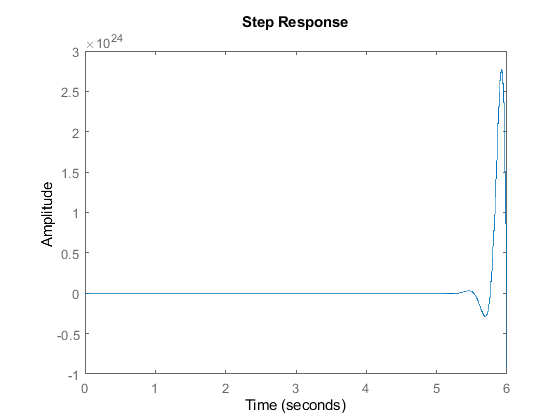

step(feedback(C_vel*sysD_vel,1))